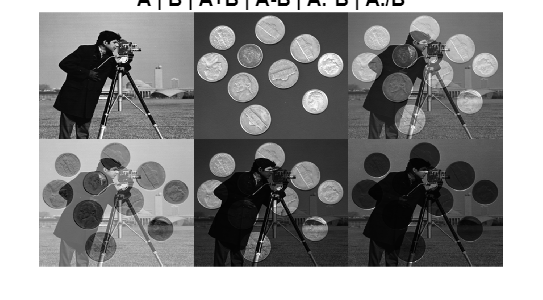

A = im2double(imread('cameraman.tif'));
B = im2double(imread('coins.png'));
A = imresize(A,size(B));

addI = A + B;
subI = A - B;
mulI = A .* B;
divI = A ./ (B + eps);

figure('Name','Task 1');
montage({A,B,mat2gray(addI),mat2gray(subI),mat2gray(mulI),mat2gray(divI)},'Size',[2 3]);
title('A | B | A+B | A-B | A.*B | A./B');

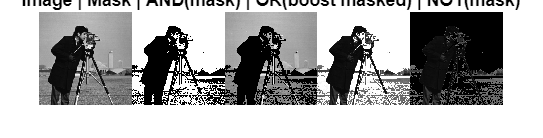


I = imread('cameraman.tif');
I = im2uint8(I);
if ndims(I)==3, I = rgb2gray(I); end
mask = I > 120;

ANDimg = I;
ANDimg(~mask) = 0;

ORimg = uint8(min(255, I + uint8(mask)*120));

NOTmask = ~mask;
NOTimg = I;
NOTimg(~NOTmask) = 0;

figure('Name','Task 2');
montage({I,mask,ANDimg,ORimg,NOTimg},'Size',[1 5]);
title('Image | Mask | AND(mask) | OR(boost masked) | NOT(mask)');

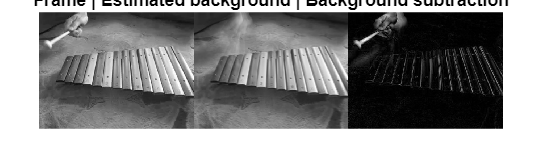


v = VideoReader('xylophone.mp4');
bgN = min(30, max(1, floor(v.FrameRate)));
acc = [];
k = 0;
v.CurrentTime = 0;
while hasFrame(v) && k < bgN
    f = readFrame(v);
    g = im2double(rgb2gray(f));
    if isempty(acc), acc = zeros(size(g)); end
    acc = acc + g;
    k = k + 1;
end
bg = acc / k;

v.CurrentTime = 0;
f1 = readFrame(v);
g1 = im2double(rgb2gray(f1));
fg1 = abs(g1 - bg);

figure('Name','Task 3');
montage({im2uint8(g1),im2uint8(bg),im2uint8(mat2gray(fg1))},'Size',[1 3]);
title('Frame | Estimated background | Background subtraction');

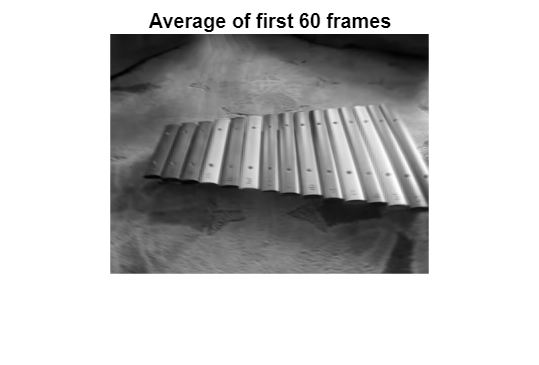


v = VideoReader('xylophone.mp4');
N = 60;
acc = [];
k = 0;
v.CurrentTime = 0;
while hasFrame(v) && k < N
    f = readFrame(v);
    g = im2double(rgb2gray(f));
    if isempty(acc), acc = zeros(size(g)); end
    acc = acc + g;
    k = k + 1;
end
avgFrame = acc / k;

figure('Name','Task 4');
imshow(avgFrame,[]); title(['Average of first ' num2str(k) ' frames']);

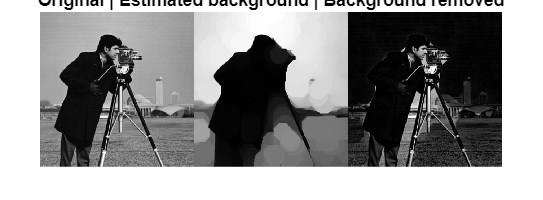


I = im2double(imread('cameraman.tif'));
bg_est = imopen(I,strel('disk',15));
I_nobg = I - bg_est;

figure('Name','Task 5');
montage({I,mat2gray(bg_est),mat2gray(I_nobg)},'Size',[1 3]);
title('Original | Estimated background | Background removed');